Load the data.

(given script)

%% Load data and perform simple first-level analyses

%
%  This cell performs simple analyses: the reversal curves and the repetition
%  curves, for each subject and condition. It also creates a massive data array
%  storing the data of all subjects and conditions, such that empirical group-
%  wise priors for model parameters (next cell) can be easily computed.

% clear MATLAB workspace
clear all
close all
clc

tasktype = 'taskid'; % task type (taskid or tasknu)
blcktype = 'test'; % block type (test or prac)

% list of block indices to be analyzed
switch blcktype
    case 'test', blcklist = [2,3,5,6]; % test blocks
    case 'prac', blcklist = [1,4]; % practice blocks
    otherwise, error('Undefined block type!');
end

% list of healthy controls
ctrllist = [ ...
    04,08,10,12,15,20,21,22,24,25, ...
    26,27,29,30,33,34,35,36,37,38, ...
    45,46,47,48,50,52,54,56,57,59, ...
    62,63,65,96];

% list of GTS patients
ptntlist = [ ...
    01,02,03,05,06,07,09,11,13,14, ...
    16,17,18,23,28,31,32,39,40,41, ...
    42,43,44,49,51,53,55,58,60,61, ...
    64,66,67,68,69,70,71,72,73,74, ...
    75,76,77,78,79,80,81,82,83,84, ...
    85,86,87,88,89,90,91,92,93,94, ...
    95,97];

% sublist of medicated patients
ptntlist_med = [ ...
    01,02,03,05,07,09,11,17,18,28, ...
    32,39,40,42,51,61,74,77,78,79, ...
    81,82,83,88,89,91];

% sublist of patients with Obsessive-Compulsive Disorder (OCD)
ptntlist_ocd = [ ...
    02,03,05,07,13,17,32,42,51,53, ...
    55,58,68,71,73,83,85,86,87,89];

% sublist of patients with Generalized Anxiety Disorder (GAD)
ptntlist_gad = [ ...
    05,13,14,17,32,42,60,67,68,77, ...
    79,80,83,85,86,87,89];

% Yale Global Tic Severity Scale (YGTSS)
% 1/ total tic severity score (over 50)
ygtss50 = [ ... % not measured for healthy controls
    08,08,20,00,19,19,15,00,18,00, ...
    25,00,12,25,00,17,08,11,09,00, ...
    00,00,14,00,00,00,00,10,00,00, ...
    23,09,00,00,00,00,00,00,16,22, ...
    26,11,05,03,00,00,00,00,15,00, ...
    20,00,06,00,30,00,00,14,00,06, ...
    14,00,00,26,00,20,12,04,12,06, ...
    08,18,26,28,28,20,18,19,19,18, ...
    17,26,10,17,10,08,08,28,16,15, ...
    23,17,09,23,22,00,24];
% 2/ total tic severity score + impairment (over 100)
ygtss100 = [ ... % not measured for healthy controls
    08,08,30,00,39,29,35,00,28,00, ...
    35,00,32,35,00,47,28,21,09,00, ...
    00,00,24,00,00,00,00,20,00,00, ...
    43,09,00,00,00,00,00,00,26,52, ...
    56,31,15,03,00,00,00,00,35,00, ...
    50,00,26,00,60,00,00,34,00,16, ...
    44,00,00,36,00,50,32,04,12,16, ...
    28,38,36,58,38,30,18,29,29,28, ...
    27,46,20,37,10,18,08,38,26,15, ...
    33,47,09,33,32,00,44];

% list of all subjects (controls and patients)
subjlist = sort([ctrllist,ptntlist]);
nsubj = numel(subjlist);

% subject type
subjtype = nan(size(subjlist));
subjtype(ismember(subjlist,ctrllist)) = 0; % healthy control
subjtype(ismember(subjlist,ptntlist)) = 1; % GTS patient

% filter YGTSS scores
ygtss50 = ygtss50(subjlist);
ygtss100 = ygtss100(subjlist);

% identify data folder
foldname = '../Data';
d = dir(foldname);

% columnize array
col = @(x)x(:);

% create big data array
dat      = [];
dat.subj = []; % subject number
dat.task = []; % task condition (1:Cb 2:Ob)
dat.sind = []; % sequence index
dat.evid = []; % sequence evidence for left response
dat.raft = []; % response given after current sequence (1:left 2:right)
dat.rbef = []; % response given before current sequence

for isubj = 1:nsubj
    
    % locate and load datafile
    filename = [];
    for ifile = 1:length(d)
        s = sscanf(d(ifile).name,'ACTOBS_S%02d');
        if numel(s) == 1 && s == subjlist(isubj)
            filename = sprintf('../Data/%s',d(ifile).name);
            break
        end
    end
    if isempty(filename)
        error('Could not find data!');
    end
    load(filename);
    disp(filename);
    
    % load data
    blkind = []; % block index within experiment
    seqind = []; % sequence index within current block
    epinum = []; % episode number within current block
    seqpos = []; % sequence position within current episode
    taskid = []; % task identifier (1:Cb 2:Ob)
    tasknu = []; % task number (1:1st 2:2nd)
    seqdir = []; % generative direction of current sequence (1:left 2:right)
    seqllr = []; % log-odds of current sequence (>0:leftwards <0:rightwards)
    seqlen = []; % sequence length
    raft   = []; % response given after current sequence (1:left 2:right)
    rbef   = []; % response given before current sequence
    jblck  = 0;
    for iblck = blcklist
        jblck = jblck+1;
        nseq = numel(expe.blck(iblck).seqdir);
        ncor = sum(expe.blck(iblck).seqdir == expe.rslt(iblck).resp(2:end));
        if strcmp(blcktype,'test')
            % check whether subject likely used flipped response mapping...
            if binocdf(ncor,nseq,0.5) < 0.05
                % ...in which case correct by flipping responses
                expe.rslt(iblck).resp = 3-expe.rslt(iblck).resp;
                pcor_blck(isubj,jblck) = 1-ncor/nseq;
                fprintf('    flipped responses for block %d!\n',jblck);
            else
                pcor_blck(isubj,jblck) = ncor/nseq;
            end
        end
        % append block information
        blkind = cat(2,blkind,jblck*ones(1,nseq));
        epinum = cat(2,epinum,expe.blck(iblck).epinum);
        seqpos = cat(2,seqpos,expe.blck(iblck).epipos);
        taskid = cat(2,taskid,expe.blck(iblck).taskid(ones(1,nseq)));
        switch blcktype
            case 'test', tasknu = cat(2,tasknu,ceil(jblck/2)*ones(1,nseq));
            case 'prac', tasknu = cat(2,tasknu,jblck*ones(1,nseq));
        end
        seqind = cat(2,seqind,(1:nseq));
        seqdir = cat(2,seqdir,expe.blck(iblck).seqdir);
        seqllr = cat(2,seqllr,expe.blck(iblck).seqllr);
        seqlen = cat(2,seqlen,expe.blck(iblck).seqlen);
        raft   = cat(2,raft,expe.rslt(iblck).resp(2:end));
        rbef   = cat(2,rbef,expe.rslt(iblck).resp(1:end-1));
        for iseq = 1:nseq
            % evidence in favor of generative category
            ls = expe.blck(iblck).seqlvl{iseq};
            % evidence in favor of left response
            ls = ls.*(3-2*expe.blck(iblck).seqdir(iseq));
            % evidence in favor of previous response
            ls = ls.*(3-2*expe.rslt(iblck).resp(iseq));
        end
    end
    
    for itask = 1:2
        
        % define task type
        switch tasktype
            case 'taskid', task = taskid; % task identifier (Cb/Ob)
            case 'tasknu', task = tasknu; % task number (1st/2nd)
            otherwise, error('Undefined task type!');
        end
        
        % filter trials of interest
        ifilt = task == itask; % include task of interest
        nfilt = nnz(ifilt);
        
        % update big data array
        dat.subj = cat(1,dat.subj,subjlist(isubj)*ones(nfilt,1));
        dat.task = cat(1,dat.task,itask*ones(nfilt,1));
        dat.sind = cat(1,dat.sind,col(seqind(ifilt)));
        dat.evid = cat(1,dat.evid,col(seqllr(ifilt)));
        dat.raft = cat(1,dat.raft,col(raft(ifilt)));
        dat.rbef = cat(1,dat.rbef,col(rbef(ifilt)));
        
    end
    
end

../Data/ACTOBS_S01_20161109_1108.mat
../Data/ACTOBS_S02_20161207-1002.mat
../Data/ACTOBS_S03_20161122-1529.mat
../Data/ACTOBS_S04_20161125-1211.mat
../Data/ACTOBS_S05_20161118_1339.mat
../Data/ACTOBS_S06_20161125-1033.mat
../Data/ACTOBS_S07_20161202-1521.mat
../Data/ACTOBS_S08_20161207-1434.mat
../Data/ACTOBS_S09_20161209-0958.mat
../Data/ACTOBS_S10_20161215-1615.mat
../Data/ACTOBS_S11_20161216-1131.mat
../Data/ACTOBS_S12_20161222-1036.mat
../Data/ACTOBS_S13_20161222-1406.mat
../Data/ACTOBS_S14_20170106-1517.mat
../Data/ACTOBS_S15_20170203-1237.mat


    flipped responses for block 1!


../Data/ACTOBS_S16_20170110-1509.mat
../Data/ACTOBS_S17_20170117-1048.mat
../Data/ACTOBS_S18_20170127-1459.mat
../Data/ACTOBS_S20_20170202-1235.mat
../Data/ACTOBS_S21_20170208-1404.mat
../Data/ACTOBS_S22_20170209-1228.mat
../Data/ACTOBS_S23_20170210-0956.mat
../Data/ACTOBS_S24_20170215-1430.mat
../Data/ACTOBS_S25_20170216-1146.mat
../Data/ACTOBS_S26_20170306-1121.mat
../Data/ACTOBS_S27_20170228-1126.mat
../Data/ACTOBS_S28_20170222-1442.mat
../Data/ACTOBS_S29_20170224-1500.mat
../Data/ACTOBS_S30_20170227-1227.mat
../Data/ACTOBS_S31_20170303-1217.mat
../Data/ACTOBS_S32_20170310-1222.mat
../Data/ACTOBS_S33_20170323-1400.mat
../Data/ACTOBS_S34_20170324-1142.mat
../Data/ACTOBS_S35_20170327-1331.mat
../Data/ACTOBS_S36_20170331-1156.mat
../Data/ACTOBS_S37_20170405-1006.mat
../Data/ACTOBS_S38_20170428-1701.mat


    flipped responses for block 3!


../Data/ACTOBS_S39_20170407-1250.mat
../Data/ACTOBS_S40_20170413-1019.mat
../Data/ACTOBS_S41_20170414-1217.mat
../Data/ACTOBS_S42_20170512-1659.mat
../Data/ACTOBS_S43_20170420-1010.mat


    flipped responses for block 3!


../Data/ACTOBS_S44_20170421-1000.mat
../Data/ACTOBS_S45_20170426-1613.mat
../Data/ACTOBS_S46_20170428-1010.mat
../Data/ACTOBS_S47_20170503-1206.mat
../Data/ACTOBS_S48_20170505-1619.mat
../Data/ACTOBS_S49_20170505-1459.mat


    flipped responses for block 4!


../Data/ACTOBS_S50_20170512-1014.mat
../Data/ACTOBS_S51_20170519-1218.mat
../Data/ACTOBS_S52_20170523-0945.mat
../Data/ACTOBS_S53_20170526-1234.mat
../Data/ACTOBS_S54_20170602-0957.mat
../Data/ACTOBS_S55_20170607-1243.mat
../Data/ACTOBS_S56_20170609-1512.mat
../Data/ACTOBS_S57_20170623-0958.mat
../Data/ACTOBS_S58_20170623-1507.mat
../Data/ACTOBS_S59_20170630-1425.mat
../Data/ACTOBS_S60_20170630-1230.mat
../Data/ACTOBS_S61_20170710-1045.mat
../Data/ACTOBS_S62_20170711-1605.mat
../Data/ACTOBS_S63_20170713-1206.mat
../Data/ACTOBS_S64_20170721-1024.mat
../Data/ACTOBS_S65_20170725-1611.mat
../Data/ACTOBS_S66_20170731-1328.mat
../Data/ACTOBS_S67_20170904-1326.mat
../Data/ACTOBS_S68_20170929-1722.mat
../Data/ACTOBS_S69_20170911-1111.mat
../Data/ACTOBS_S70_20170914-1002.mat
../Data/ACTOBS_S71_20170918-1305.mat
../Data/ACTOBS_S72_20170919-1123.mat
../Data/ACTOBS_S73_20170925-1300.mat
../Data/ACTOBS_S74_20170927-1335.mat
../Data/ACTOBS_S75_20171002-1207.mat
../Data/ACTOBS_S76_20171003-1445.mat
.

Inital fits ('nrep' number of fits) of the actual data to obtain an estimate of the two variables of interest, the probability of reversal (prev) and the learning error (beta), that will serve fixed refence values to the next analyses.

nrep = 1e1;

prev_fit = nan(nsubj,2);
beta_fit = nan(nsubj,2);

for irep = 1:nrep
    for isubj = 1:nsubj
        %isubj
        for itask = 1:2
            
            % filter trials of interest
            ifilt = dat.subj == subjlist(isubj) & dat.task == itask;
            
            % fit model
            cfg_fit        = [];
            cfg_fit.seqllr = dat.evid(ifilt);
            cfg_fit.seqind = dat.sind(ifilt);
            cfg_fit.rbef   = dat.rbef(ifilt);
            cfg_fit.raft   = dat.raft(ifilt);
            cfg_fit.brep   = 0; % force no repetition bias
            cfg_fit.epsi   = 0; % force no lapses
            
            out_fit = fit_model_softmax(cfg_fit);
            
            % store model parameters
            prev_fit(isubj,itask,irep) = out_fit.prev;
            beta_fit(isubj,itask,irep) = out_fit.beta;
    
        end
    end
end

prev_fix = mean(mean(prev_fit, 3), 1);
beta_fix = mean(mean(beta_fit, 3), 1);

Using a (given) function "sim_model_softmax", dataset are simulated using the fixed parameters (as the parameters differs across the 2 tasks, we end up with nsim simulated datasets).

nsim              = 1000; % number of simulations

nsim = 1000

nsubjsubset       = [12 24 48 96] % number of participants (w/out consideration for medical condition, 96 = all)

nsubjsubset =     12    24    48    96



prev_diff_subjave = zeros(nsim,2,length(nsubjsubset));
beta_diff_subjave = zeros(nsim,2,length(nsubjsubset));

for isubjsubset = nsubjsubset

    prev_recov = nan(isubjsubset,2,nsim);
    beta_recov = nan(isubjsubset,2,nsim);
    
    isubjsubset
    seq_isubjsubsest = randperm(nsubj,isubjsubset)
    for isubj = seq_isubjsubsest
        for itask = 1:2
            
            % filter trials of interest
            ifilt = dat.subj == subjlist(isubj) & dat.task == itask;
            
            % simulate model
            cfg_sim        = [];
            cfg_sim.nsim   = nsim;
            cfg_sim.seqllr = dat.evid(ifilt);
            cfg_sim.seqind = dat.sind(ifilt);
            cfg_sim.prev   = prev_fix(itask);
            cfg_sim.beta   = beta_fix(itask);
            cfg_sim.brep   = 0; % force no repetition bias
            cfg_sim.epsi   = 0; % force no lapses
            
            out_sim        = sim_model_softmax(cfg_sim);
        

        Then each datasets is fit using the (given) function "fit_model_softmax".

            % fit simulated decisions
            for isim = 1:nsim
                cfg_fit        = [];
                cfg_fit.seqllr = out_sim.cfg.seqllr;
                cfg_fit.seqind = out_sim.cfg.seqind;
                cfg_fit.raft   = out_sim.raft(:,isim);
                cfg_fit.rbef   = out_sim.rbef(:,isim);
                cfg_fit.brep   = out_sim.cfg.brep; % force no repetition bias
                cfg_fit.epsi   = out_sim.cfg.epsi; % force no lapses
                    
                out_recov = fit_model_softmax(cfg_fit);
                

        Estimated value of prev and beta from each simulation are stored and their average value is computed.

                % store model parameters
                revindexsubj = find(seq_isubjsubsest==isubj);
                % isubj goes over the index limit --> reverse indexing with 
                % find(seq_isubjsubsest == isubj)
                prev_recov(revindexsubj,itask,isim) = out_recov.prev;
                beta_recov(revindexsubj,itask,isim) = out_recov.beta;
            end    
        end
    end

        Histogram of the recovered parameters and their difference from the fix one.

    
    
    
    prev_recov_totave  = mean(prev_recov(:));
    beta_recov_totave  = mean(beta_recov(:));
    
    % Concatenation not needed as both tasks are separately taken into consideration    
    %prev_recov_cattask = squeeze(cat(3,prev_recov(:,1,:),prev_recov(:,2,:)))';
    %beta_recov_cattask = squeeze(cat(3,beta_recov(:,1,:),beta_recov(:,2,:)))';
    
    prev_recov_subjave = squeeze(mean(prev_recov,1))';
    beta_recov_subjave = squeeze(mean(beta_recov,1))';
    
    figure;
    hold on
    title(["Probability of reversal, Cb (from n = ",num2str(isubjsubset)," subjects)"]);
    hist(prev_recov_subjave(:,1));
    hold off
    
    figure;
    hold on
    title(["Probability of reversal, Ob (from n = ",num2str(isubjsubset)," subjects)"]);
    hist(prev_recov_subjave(:,2));
    hold off
    
    
    figure;
    hold on
    title(["Learning error, Cb (from n = ",num2str(isubjsubset)," subjects)"]);
    hist(beta_recov_subjave(:,1));
    hold off
    
    figure;
    hold on
    title(["Learning error, Ob (from n = ",num2str(isubjsubset)," subjects)"]);
    hist(beta_recov_subjave(:,2));
    hold off
    
    
    prev_diff = prev_recov - prev_fix;
    beta_diff = beta_recov - beta_fix;
    
    prev_diff_totave  = mean(prev_diff(:));
    beta_diff_totave  = mean(beta_diff(:));
    
    % Concatenation not needed as both tasks are separately taken into consideration   
    %prev_diff_cattask = squeeze(cat(3, prev_diff(:, 1, :), prev_diff(:,2,:)))';
    %beta_diff_cattask = squeeze(cat(3, beta_diff(:, 1, :), beta_diff(:,2,:)))';
    

            Parameters for each stimulation (average across subjects) is stored outside the loop.

    revindexsubset = find(nsubjsubset==isubjsubset);
    prev_diff_subjave(:,:,revindexsubset) = squeeze(mean(prev_diff,1))';
    beta_diff_subjave(:,:,revindexsubset) = squeeze(mean(beta_diff,1))';
    
    figure;
    hold on
    title(["Difference recovered-fixed probability of reversal, Cb (from n = ",num2str(isubjsubset)," subjects)"]);
    hist(prev_diff_subjave(:,1,revindexsubset));
    hold off
    
    figure;
    hold on
    title(["Difference recovered-fixed probability of reversal, Ob (from n = ",num2str(isubjsubset)," subjects)"]);
    hist(prev_diff_subjave(:,2,revindexsubset));
    hold off
    
    
    figure;
    hold on
    title(["Difference recovered-fixed learning error, Cb (from n = ",num2str(isubjsubset)," subjects)"]);
    hist(beta_diff_subjave(:,1,revindexsubset));
    hold off
    
    figure;
    hold on
    title(["Difference recovered-fixed learning error, Ob (from n = ",num2str(isubjsubset)," subjects)"]);
    hist(beta_diff_subjave(:,2,revindexsubset));
    hold off

        Correlation between the two parameters between subject is computed for each simulation.  

isubjsubset = 12

seq_isubjsubsest =      5    26    70    46    35    32     2    96    80    40    87    63


mean_corr_prev_beta =     0.3075    0.4095


shared_var_prev_beta =     0.0945    0.1677


isubjsubset = 24

seq_isubjsubsest =     47    35    85    61    37    16    90    52    48     7    26    71    43    84    49    57    89    18    63    11    42    82    21    66


mean_corr_prev_beta =     0.3127    0.3935


shared_var_prev_beta =     0.0978    0.1548


isubjsubset = 48

seq_isubjsubsest =     77     6     3    63    56    49    53    71    28    78    24    73    60    88    55    21    43    12    65    38     7    17    84    58    85    87    52    13    34    90    27    40    95    39    80    62    57    75     5    59    32    48    94    86     4    42    45    23


mean_corr_prev_beta =     0.3197    0.3909


shared_var_prev_beta =     0.1022    0.1528


isubjsubset = 96

seq_isubjsubsest =     34    92    66    43     4    71    73    56    63    90    61    85    32    55    59    47    38    81    12    74    75    46    67    87    89    54    31    94    16    88    45    91    78    30    39    36     2    72     9    69    17    41    76    93    24    25    86    21    70    13


mean_corr_prev_beta =     0.3151    0.3886


shared_var_prev_beta =     0.0993    0.1510


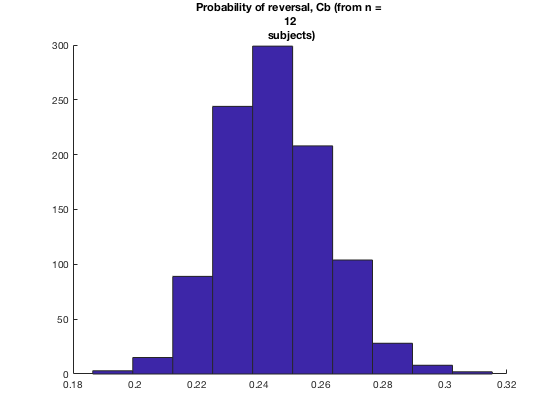

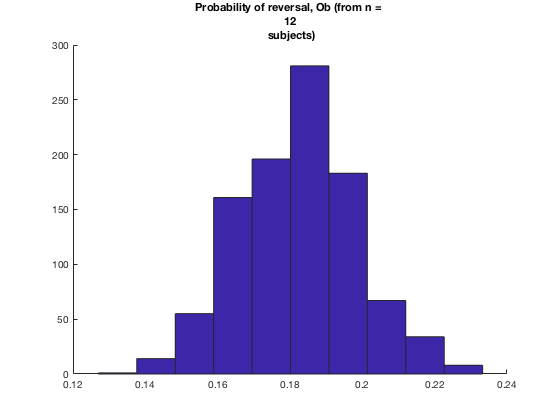

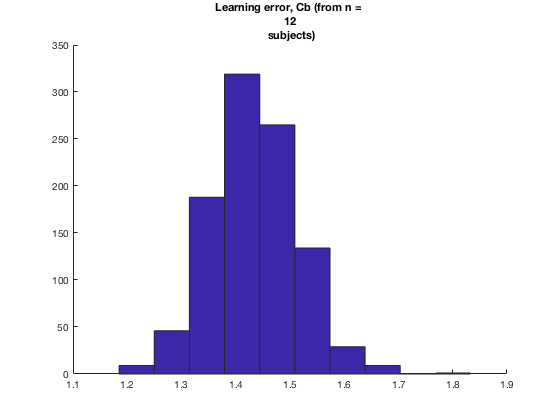

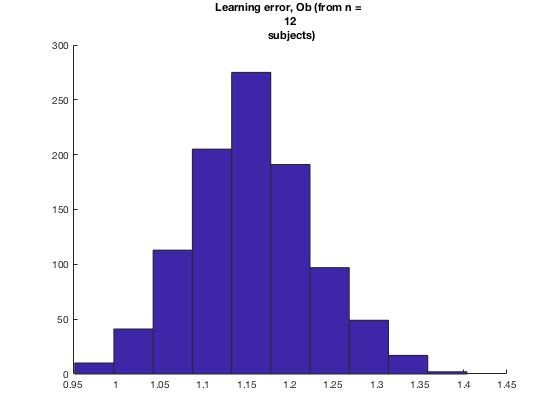

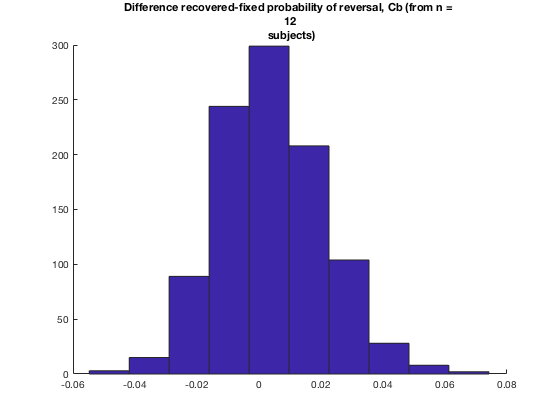

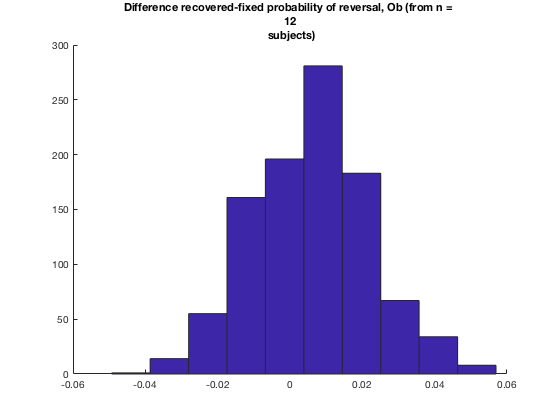

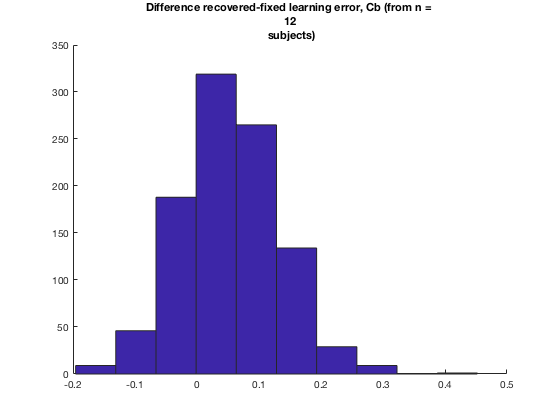

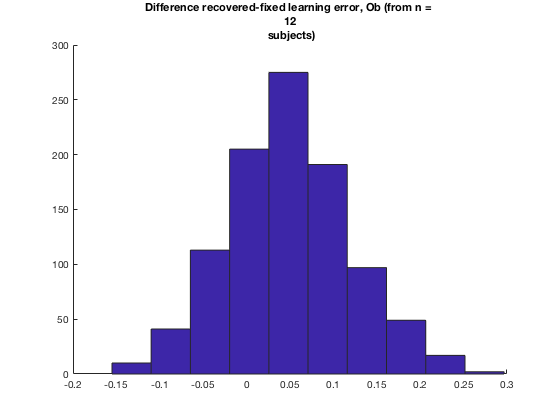

    % Concatenation not needed as both tasks are separately taken into consideration 
    %prev_recov_cattask = squeeze(cat(3,prev_recov(:,1,:),prev_recov(:,2,:)));
    %beta_recov_cattask = squeeze(cat(3,beta_recov(:,1,:),beta_recov(:,2,:)));
    
    corr_prev_beta = zeros(nsim, 2);
       
    for itask = 1:2
        for isim = 1:nsim
            corr_prev_beta(isim,itask) = corr(prev_recov(:,itask,isim), beta_recov(:,itask,isim));
        end
    end
    
    mean_corr_prev_beta = mean(corr_prev_beta,1)
    shared_var_prev_beta = mean_corr_prev_beta.^2
    
end

Histogram of the paramterer according the number of subject they were estimated from (n = 12, 24, 48 or 96).

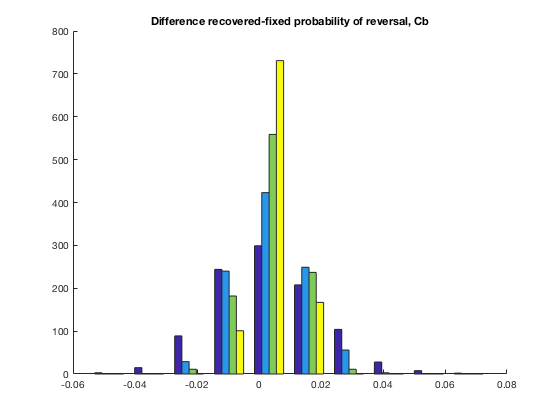

figure;
hold on
title(["Difference recovered-fixed probability of reversal, Cb"]);
hist(prev_diff_subjave(:,1,:));  
hold off

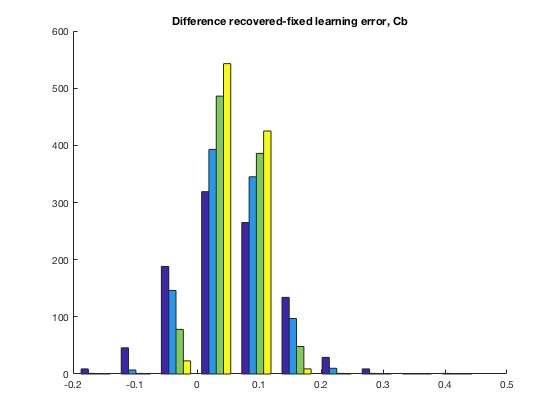

    
figure;
hold on
title(["Difference recovered-fixed learning error, Cb"]);
hist(beta_diff_subjave(:,1,:)); 
hold off

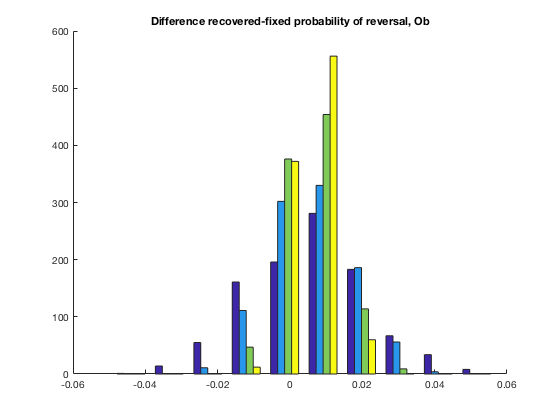



figure;
hold on
title(["Difference recovered-fixed probability of reversal, Ob"]);
hist(prev_diff_subjave(:,2,:));  
hold off

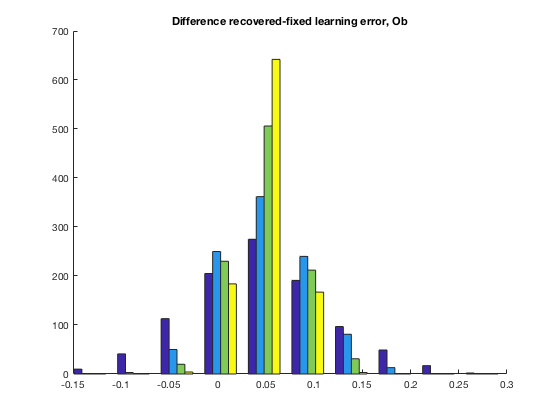

    
figure;
hold on
title(["Difference recovered-fixed learning error, Ob"]);
hist(beta_diff_subjave(:,2,:)); 
hold off